% Delete rows in the data_set that contain missing data
data_pr = rmmissing(data_pr);
% Randomly divide the data set into 70% training set 
% and 30% validation set
sz = size(data_pr);
col_sum = sz(1, 1);
col_training = round(col_sum*0.7);
row_idx_T = randperm(col_sum, col_training); % 70%
row_idx_V = [];

for i = 1:col_sum
    if ~ismember(i, row_idx_T)
        row_idx_V = [row_idx_V, i];
    end
end

training = data_pr(row_idx_T, :);
validation = data_pr(row_idx_V, :);

% Assign independent variables and response variables
x_T = training(:, 1); % Protein
y_T = training(:, 2); % Nitrogen
x_V = validation(:, 1);
y_V = validation(:, 2);

x_max = max(x_T);
x_min = min(x_T);
y_max = max(y_T);
y_min = min(y_T);

x = linspace(x_min, x_max);

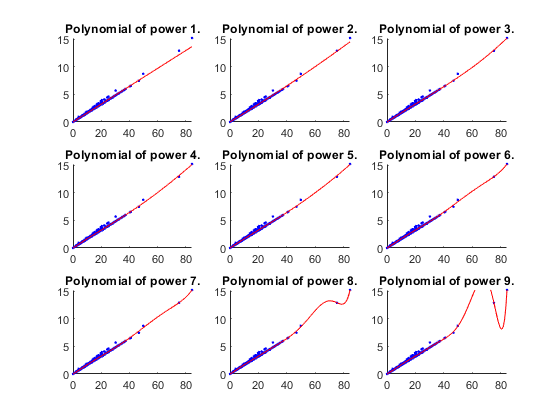

%Create figure of Data and fitted polynomials. To see clearly, 
% break it into 9 subplots.
%For each subplot, plot training data set and fitted polynomial.
figure
trainError = zeros(9,col_training);
valError = zeros(9,col_sum-col_training);
trainSSE = zeros(9,1);
valSSE = zeros(9,1);

for R = 1:9
subplot(3,3,R);
hold on;

%Plot training data.
scatter(x_T, y_T, ".b");
% scatter(x_V, y_V, ".g");

%Create polynomial function that tries to fit training data.
poly = polyfit(x_T, y_T, R);

%Calculate y value at each x value, using polynomial function.
yfitted = polyval(poly, x);
plot(x, yfitted, 'r');

xlim([x_min, x_max]);
ylim([y_min, y_max]);
title(sprintf('Polynomial of power %d.', R));
hold off;

trainError(R,:) = y_T - polyval(poly, x_T);
valError(R,:) = y_V - polyval(poly,x_V);
trainSSE(R) = sum(trainError(R,:).^2);
valSSE(R) = sum(valError(R,:).^2);

end

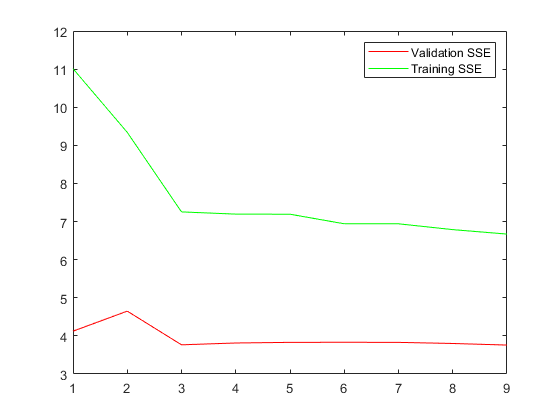

%Plot figure of Error vs. polynomial order
figure
plot(1:9,valSSE,'r',1:9,trainSSE,'g');
legend('Validation SSE','Training SSE');